Problem 14

clear
syms t real positive
g = 9.81;
m1 = 5e-3, m2 = 3e-3

m1 = 0.0050

m2 = 0.0030

Determine the angle

th = acosd(1/2)

th = 60.0000

Motion of the mass 1 and 2

r1 = [10*t; 0]

$$r1 = \left(\begin{array}{c} 10\,t\\ 0 \end{array}\right)$$

v20 = 20*[cosd(th); sind(th)]

v20 =    10.0000
   17.3205


r2 = v20*t + 1/2*[0; -g]*t^2

$$r2 = \left(\begin{array}{c} 10\,t\\ 10\,\sqrt{3}\,t-\frac{981\,t^{2}}{200} \end{array}\right)$$

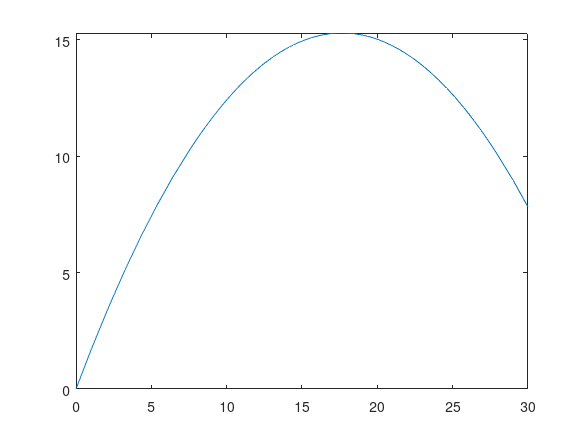

fplot(r2(1),r2(2),[0 3])

(a) Maximum height Hmax reached by the com of the two particle

rc = (m1*r1+m2*r2)/(m1+m2)

$$rc = \left(\begin{array}{c} 10\,t\\ \frac{15\,\sqrt{3}\,t}{4}-\frac{2943\,t^{2}}{1600} \end{array}\right)$$

vc = diff(rc,t)

$$vc = \left(\begin{array}{c} 10\\ \frac{15\,\sqrt{3}}{4}-\frac{2943\,t}{800} \end{array}\right)$$

tmax = solve(vc(2)==0,t)

$$tmax = \frac{1000\,\sqrt{3}}{981}$$

Hmax = vpa(subs(rc(2),t,tmax))

$$Hmax = 5.7339449541284403669724770642202$$

(b) and velocity

vc = double(subs(vc,t,tmax))

vc =     10
     0


(c) Acceleration

ac = double(diff(vc,t))

ac =      0
     0
